# **Signals and Systems**

## **Lab **

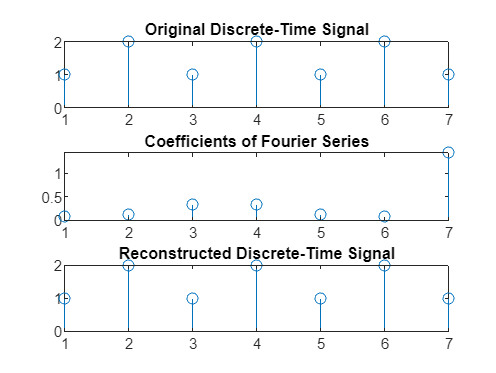

x = [1 2 1 2 1 2 1];
N = length(x);
ak = DTFS(x, N);
x1 = IDTFS(ak, N);
subplot(3,1,1);
stem(abs(x));
title('Original Discrete-Time Signal');
subplot(3,1,2);
stem(abs(ak));
title('Coefficients of Fourier Series');
subplot(3,1,3);
stem(abs(x1));
title('Reconstructed Discrete-Time Signal');

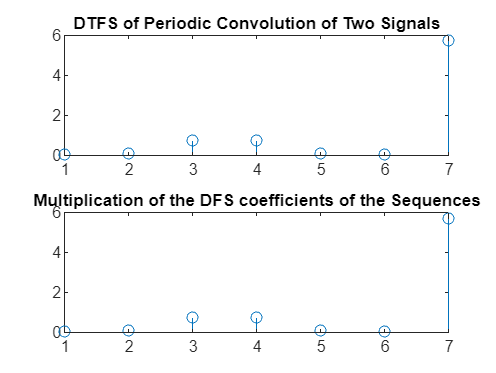

x=[1 2 1 2 1 2 1];
y=[1 0 1 0 1 0 1];

z = periodic_convolution(x,y);
LHS = DTFS(z,N);

figure;
subplot(2,1,1);
stem(abs(LHS));
title('DTFS of Periodic Convolution of Two Signals');

ak = DTFS(x,N);
bk = DTFS(y,N);
N = length(x);

RHS = N.*ak.*bk;
subplot(2,1,2);
stem(abs(RHS));
title('Multiplication of the DFS coefficients of the Sequences');

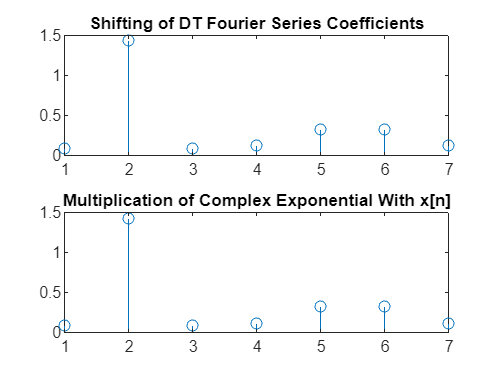

a = zeros(1:N);
%M = input("Enter value of shift: ");
M = 9;
% LHS
for n = 1:N
 a(n) = exp(1i * 2 * pi * M * (n/ N)) * x (n);
end

LHS = DTFS(a,N);

figure;
subplot(2,1,1);
stem(abs(LHS));
title('Shifting of DT Fourier Series Coefficients');

% RHS
z = DTFS(x,N);
RHS = circshift(z, [0 M]);

subplot(2,1,2);
stem(abs(RHS));
title('Multiplication of Complex Exponential With x[n]')

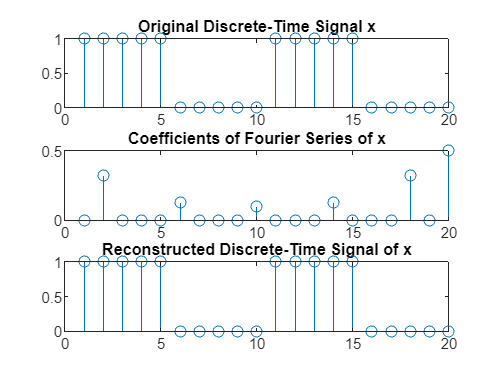

A = [ones(1,5) zeros(1,5)];
x = [A A];
N = length(x);

x_DTFS =  DTFS(x,N);
x_IDTFS = IDTFS(x_DTFS,N);

figure;
subplot(3,1,1);
stem(abs(x));
title('Original Discrete-Time Signal x');
subplot(3,1,2);
stem(abs(x_DTFS));
title('Coefficients of Fourier Series of x');
subplot(3,1,3);
stem(abs(x_IDTFS));
title('Reconstructed Discrete-Time Signal of x');